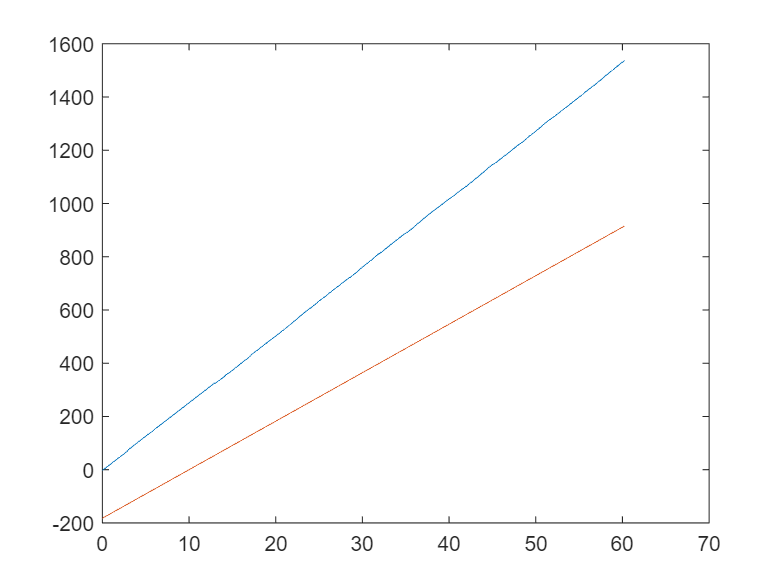

clear;close all
%The simulation use for signal processing in wavenumber scanning domains
% of white-light interferometers. In the simulation, The IFT(Inverse Fourie
% -r Transform) of I can be get.
%Creat guass function:
%      iSigma =  a1*exp(-((sigma-b1)/c1)^2)
%Coefficients (with 95% confidence bounds):
%        a1 =       568.8
%        b1 =        1.45  
%        c1 =      0.3129
%Creat a phase functoion:
%      pSigma = -4*pi*z0*sigma;

%Related parameters
%intensityMark,phaseMark,ifftIntenMark,ifftPhaseMark:image identification
intensityMark = 221;
phaseMark = 223;
ifftIntenMark = 222;
ifftPhaseMark = 224;
%npoint:sampling point 
nPoint = 2^18;
z0 = 10;
sigma = 0:0.0083:(nPoint-1)*0.0083;
fSigma = 568.8*exp(-((sigma-2)/0.3129).^2);
pSigma = -4*pi*z0*sigma;
iSigma = fSigma.*exp(1i*pSigma);
%calculate ifft of iSigma
[intensity,phase,zData]=ifftOfIsigma(iSigma,sigma(1),sigma(end),nPoint);
% zeroPhase = findZeroPhase(zDataInter,phase,0);

plot(zData,phase);

% k = 10;
% phase2222 = interpn(zData,phase,k,'linear');

hold on
plot(zData,4*pi*1.45*(zData-z0));

zData(round(length(zData)/6))

ans =   10.040007441876881


phase(round(length(zData)/6))

ans =      2.523329089710981e+02


4*pi*1.45*(zData(round(length(zData)/6))-z0)

ans =    0.728985095838114


difference=phase(round(length(zData)/6))-4*pi*1.45*(zData(round(length(zData)/6))-z0)

difference =      2.516039238752600e+02


phase_pi=4*pi*1.45*((10-(1/(1.45*4))-z0))+difference;



diff = 0.1;
%limit the range of zData,about (zp-lambda/8,zp+lambda/8)
% LimZData = zData(zData>(10-(1/1.45)/8)&zData<(10+(1/1.45)/8));
% phaseData = phaseData(zData>(10-(1/1.45)/8)&zData<(10+(1/1.45)/8));
positivePhase = phase(phase>phase_pi);
negativePhase = phase(phase<phase_pi);
while true 
    if length(find(abs(positivePhase-phase_pi)<diff))>1
       lastDiff = diff;
       diff = diff/2;
    elseif (isempty(find(abs(positivePhase-phase_pi)<diff, 1)))
        diff = (diff + lastDiff)/2;
    else
        zeroPhase1= positivePhase(abs(positivePhase-phase_pi)<diff);
        break
    end
end
while true 
    if length(find(abs(negativePhase-phase_pi)<diff))>1
       lastDiff = diff;
       diff = diff/2;
    elseif (isempty(find(abs(negativePhase-phase_pi)<diff, 1)))
        diff = (diff + lastDiff)/2;
    else
        zeroPhase2= negativePhase(abs(negativePhase-phase_pi)<diff);
        break
    end
end
zeroData1 = zData(phase==zeroPhase1);
zeroData2 = zData(phase==zeroPhase2);
zeroPhase = ((phase_pi-zeroPhase2)*(zeroData1-zeroData2))/(zeroPhase1-zeroPhase2)...
            +zeroData2

zeroPhase =    9.886002046516143


function [intensity,phase,zData]=ifftOfIsigma(input,sigmaStart,sigmaEnd,nPoint)
%This function use for calculating ifft of iSigma.
%The output is intensity and phase after ifft.
deltaSigma = (sigmaEnd-sigmaStart)/(nPoint-1);
deltaZ = 1/(2*nPoint*deltaSigma);
zData = (0:(nPoint-1))*deltaZ;
ifftIsigma = ifft(input);
intensity = abs(ifftIsigma);
phase0 = angle(ifftIsigma);
phase =unwrap(phase0);
% phase = atan(imag(ifftIsigma)./real(ifftIsigma));
% phase=phasewrap(phase);
% %interpolation
% zDataInter = linspace(zData(1),zData(end),nPoint*10);
% intensity = interpn(zData,intensity,zDataInter,'linear');
%  phase = interpn(zData,phase,zDataInter,'linear');
end

function zeroPhase = findZeroPhase(zData,phaseData,zeroPoint)
diff = 0.1;
%limit the range of zData,about (zp-lambda/8,zp+lambda/8)
LimZData = zData(zData>(10-(1/1.45)/8)&zData<(10+(1/1.45)/8));
phaseData = phaseData(zData>(10-(1/1.45)/8)&zData<(10+(1/1.45)/8));
% phaseData = phaseData()
positivePhase = phaseData(phaseData>0);
negativePhase = phaseData(phaseData<0);
while true 
    if length(find(abs(positivePhase-zeroPoint)<diff))>1
       lastDiff = diff;
       diff = diff/2;
    elseif (isempty(find(abs(positivePhase-zeroPoint)<diff, 1)))
        diff = (diff + lastDiff)/2;
    else
        zeroPhase1= positivePhase(abs(positivePhase-zeroPoint)<diff);
        break
    end
end
while true 
    if length(find(abs(negativePhase-zeroPoint)<diff))>1
       lastDiff = diff;
       diff = diff/2;
    elseif (isempty(find(abs(negativePhase-zeroPoint)<diff, 1)))
        diff = (diff + lastDiff)/2;
    else
        zeroPhase2= negativePhase(abs(negativePhase-zeroPoint)<diff);
        break
    end
end
zeroData1 = LimZData(phaseData==zeroPhase1);
zeroData2 = LimZData(phaseData==zeroPhase2);
zeroPhase = ((0-zeroPhase2)*(zeroData1-zeroData2))/(zeroPhase1-zeroPhase2)...
            +zeroData2;
end

function setImage(imageMark,xData,yData,xlabel,ylabel,zeroPhase)
%This function setImage use for setting image property, such as axes, line,
%colour and so on. 
%ampMaxZ:The abscissa where the maximum amplitude value is located.
global ampMaxZ
yDataLine = plot(xData,yData);
%Find the max of Intensity.
[yDataMax,yDataMaxindex]= max(yData);
%Set the location of the tick marks along the axis
if imageMark == 221
    hold on
    ampMaxZ = xData(yDataMaxindex);
    yMaxLine = plot([xData(yDataMaxindex),xData(yDataMaxindex)],...
               [0,yDataMax]);
    set(gca,'Xlim',   [xData(yDataMaxindex)-0.7 xData(yDataMaxindex)+0.7]);
    set(yDataLine,'color',      'blue',...
                  'LineStyle',  '-',...
                  'LineWidth',   2);
    set(yMaxLine, 'color',       'k',...
                  'LineStyle',  '--',...
                  'LineWidth',   2);
elseif imageMark == 223
    set(gca,'Xlim',   [ampMaxZ-0.7 ampMaxZ+0.7]);
    set(yDataLine,'color',      'blue',...
                  'LineStyle',  '-',...
                  'LineWidth',   2);
elseif imageMark == 222
    hold on
    ampMaxZ = xData(yDataMaxindex);
    yMaxLine = plot([xData(yDataMaxindex),xData(yDataMaxindex)],...
               [0,yDataMax]);
    set(yDataLine,'color',      'blue',...
                  'LineStyle',  '-',...
                  'LineWidth',   2);
    set(yMaxLine, 'color',       'k',...
                  'LineStyle',   '--',...
                  'LineWidth',    2);
    set(gca,'Xlim',   [xData(yDataMaxindex)-2 xData(yDataMaxindex)+2]);
else
    hold on
    zeroLine = plot([ampMaxZ-2,ampMaxZ+2],[0,0]);
    zeroPhaseLine = plot([zeroPhase,zeroPhase],[-3.14,0]);
    set(gca,'Xlim', [ampMaxZ-2 ampMaxZ+2]);
    set(gca,'Ylim', [-3.14 3.14]);
    set(yDataLine,'color',      'blue',...
                  'LineStyle',  '-',...
                  'LineWidth',   2);
    set(zeroLine, 'color',       'k',...
                  'LineStyle',   '--',...
                  'LineWidth',    2);
    set(zeroPhaseLine, 'color',  'k',...
                  'LineStyle',   '--',...
                  'LineWidth',    2);
end

set(gca,'Xcolor',     [0 0 0],...
        'Ycolor',     [0 0 0],...
        'Color' ,     [1 1 1],...
        'FontName',   'Arial',...
        'FontAngle',  'normal',...
        'FontSize',    13);
%Set label names for X coordinates and Y coordinates
set(get(gca,'XLabel'), 'String',xlabel,...
                       'FontName','Arial',...
                       'FontSize',14);
set(get(gca,'YLabel'), 'String',ylabel,...
                       'FontName','Arial',...
                       'FontSize',14);
end

function xu = phasewrap(xw)
xu = xw;
for i = 2:length(xw)
        diff = xw(i) - xw(i-1);
        if diff > pi/2
            xu(i:end) = xu(i:end) - pi;
        elseif diff < -pi/2
            xu(i:end) = xu(i:end) + pi;
        end
end
end